# Modeling System Architecture of Keyless Entry System

This example shows how to set up the architecture for a keyless entry system for a vehicle in System Composer™. You also learn how to create different architecture views for different stakeholder concerns. This example follows a model-based systems engineering (MBSE) workflow:

- Define Stakeholder Requirements

- Define Architecture Model

- Define Stereotypes to Classify Components

- Define Port Interfaces to Describe Data Flow

- Create Views to Present to Stakeholders

openProject("scKeylessEntrySystem");

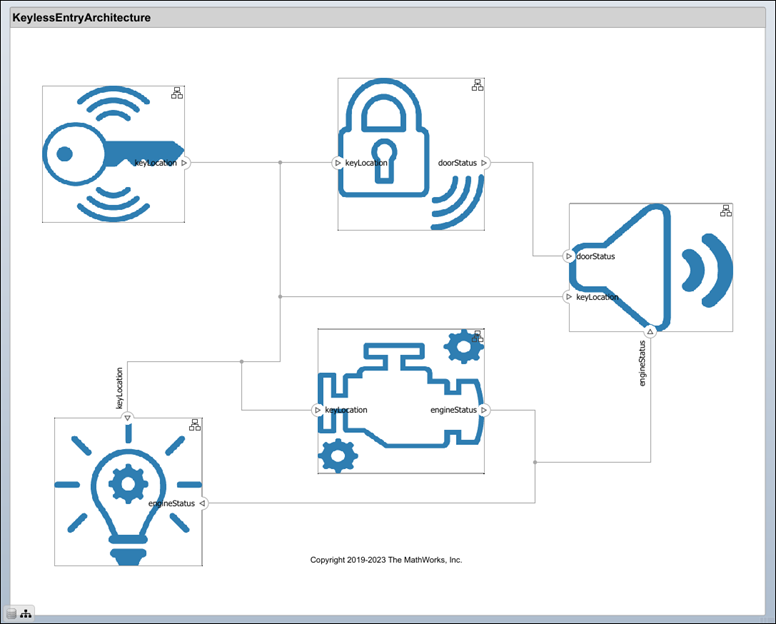

For more information about mask icons on components, see [Compose Architectures Visually](docid:systemcomposer_ug#mw_a2a9882c-f8f7-4759-a291-00136b91f132).

## **Define Stakeholder Requirements**

In MBSE design, functional requirements represent high-level stakeholder requirements based on needs and concerns for the design to address. Run this command to open the [**Requirements Editor**](docid:slrequirements_ref#mw_4a55c395-b21a-4116-93ef-2b39c1a0fd67) with the functional requirements. A Requirements Toolbox™ license is required to inspect requirements in a System Composer architecture model.

slreq.load('FunctionalRequirements');

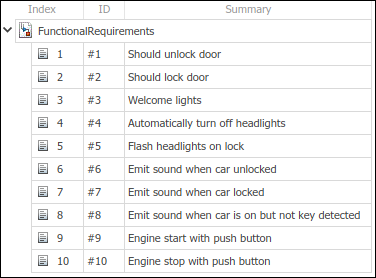

These stakeholder requirements specify that the architecture model must include a door lock and unlock system, a lighting control system, a sound system, and an engine control system. These components should meet requirements after passing quality checks. For more information, see [Manage Requirements](docid:systemcomposer_ug#mw_25461fc9-0a67-4f60-8387-0bfc3011d04c).

## **Define Architecture Model**

The architecture of a keyless entry system includes sensors, a mechanical door lock system, a lighting system, a sound system, and an engine control system. These components interact based on the information passed through their ports by connections. Each top-level component can be decomposed into its subcomponents to represent an architectural hierarchy.

### Decompose the FOB Locator System

The `FOB Locator System` component includes the system the vehicle uses to receive a wireless signal and isolate the location of the key to lock or unlock doors. This action is the first step in implementing a keyless entry system.

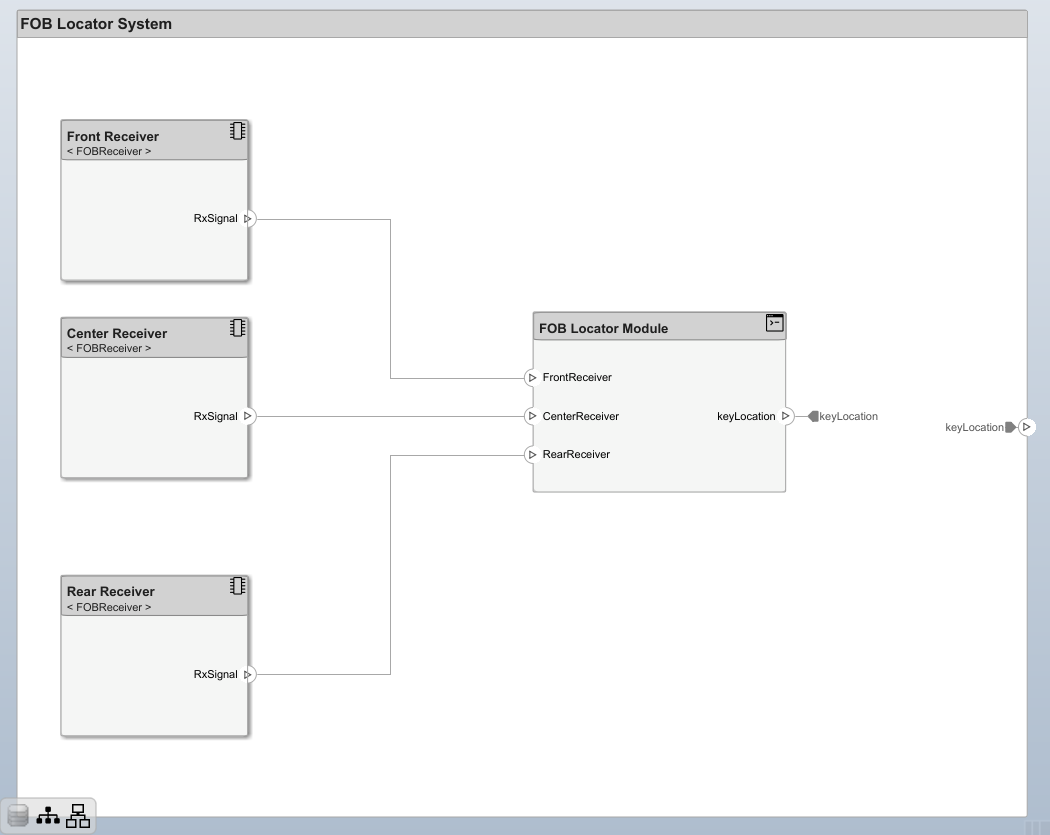

The referenced architecture `FOB Receiver` is reused to type the three receivers on the vehicle on the front, center, and rear. Each receiver sends a signal, `RxSignal`, to the `FOB Locator Module` component that determines the key location, `keyLocation`, and transmits the key location to all the other systems represented by components.

### Decompose the Door Lock and Unlock System

After the key location is identified, the automated door lock and unlock system activates. The door lock and unlock system has both hardware and software components.

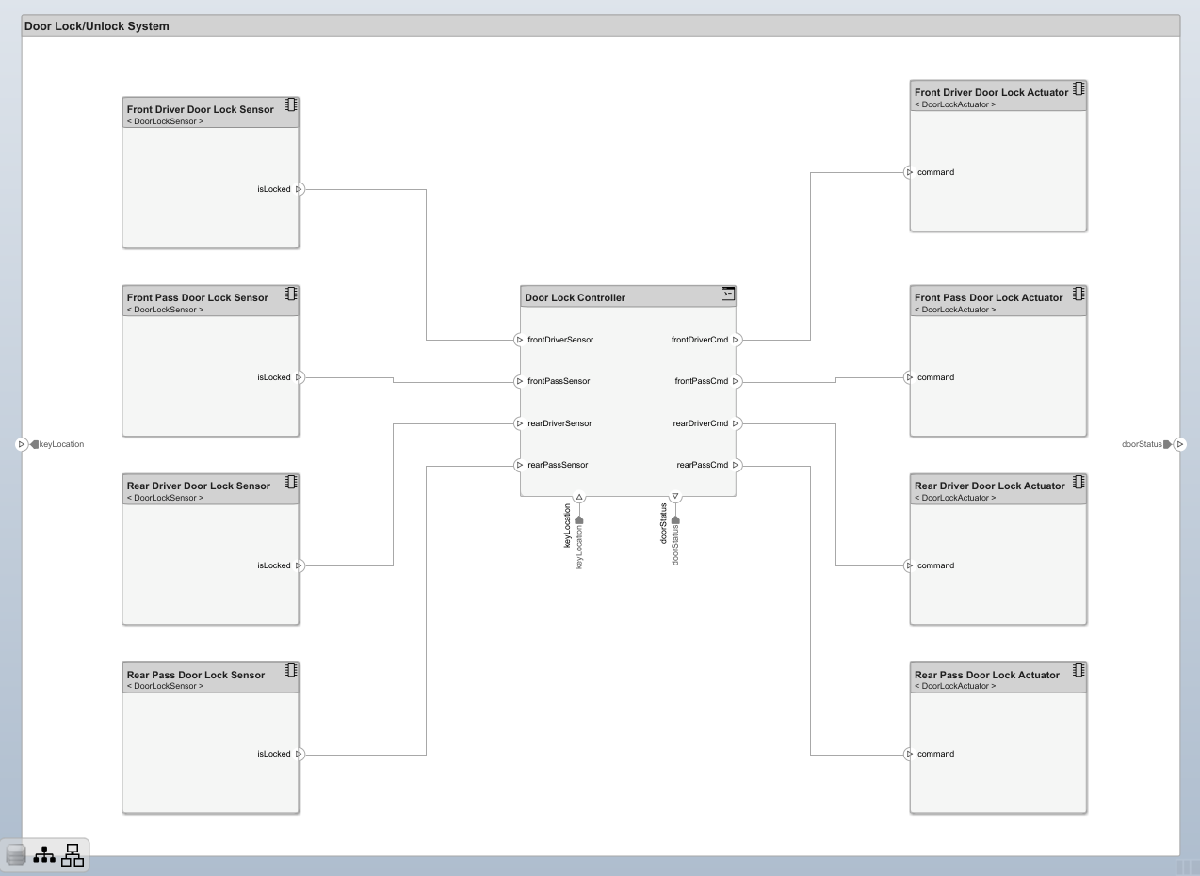

All four doors for the vehicle have sensors that detect whether the door is locked. The `DoorLockSensor` referenced architecture types these components. According to the information passed through the FOB, the `Door Lock Controller` component activates the actuators for the four doors to optionally implement the door locks. The `DoorLockActuator` referenced architecture types the actuators. The door lock status `doorStatus` is transmitted through the boundary from the `Door Lock Controller` component.

### Decompose the Sound System

The `Sound System` component controls emitting sounds to indicate key location, door status, and engine status.

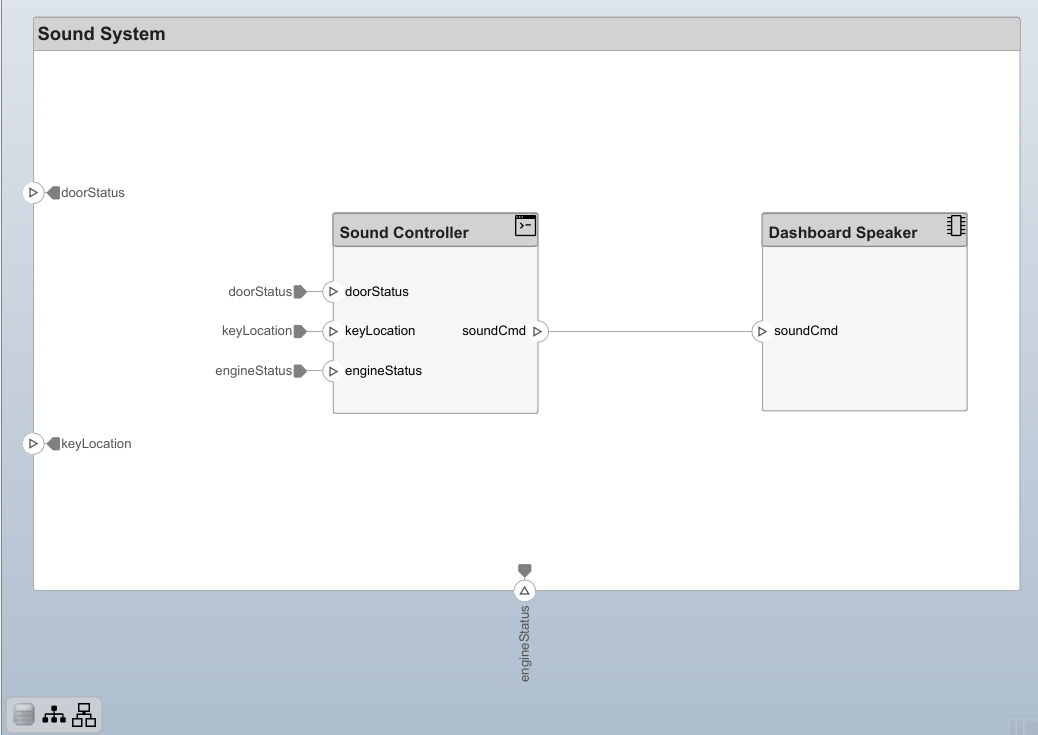

The software for the `Sound Controlle`r component sends a command to the `Dashboard Speaker` component to process and make the sounds.

### Decompose the Engine Control System

The engine control system contains a system to control the brakes, transmission, and engine. The keyless entry system activates a keyless start controller that starts or stops the vehicle.

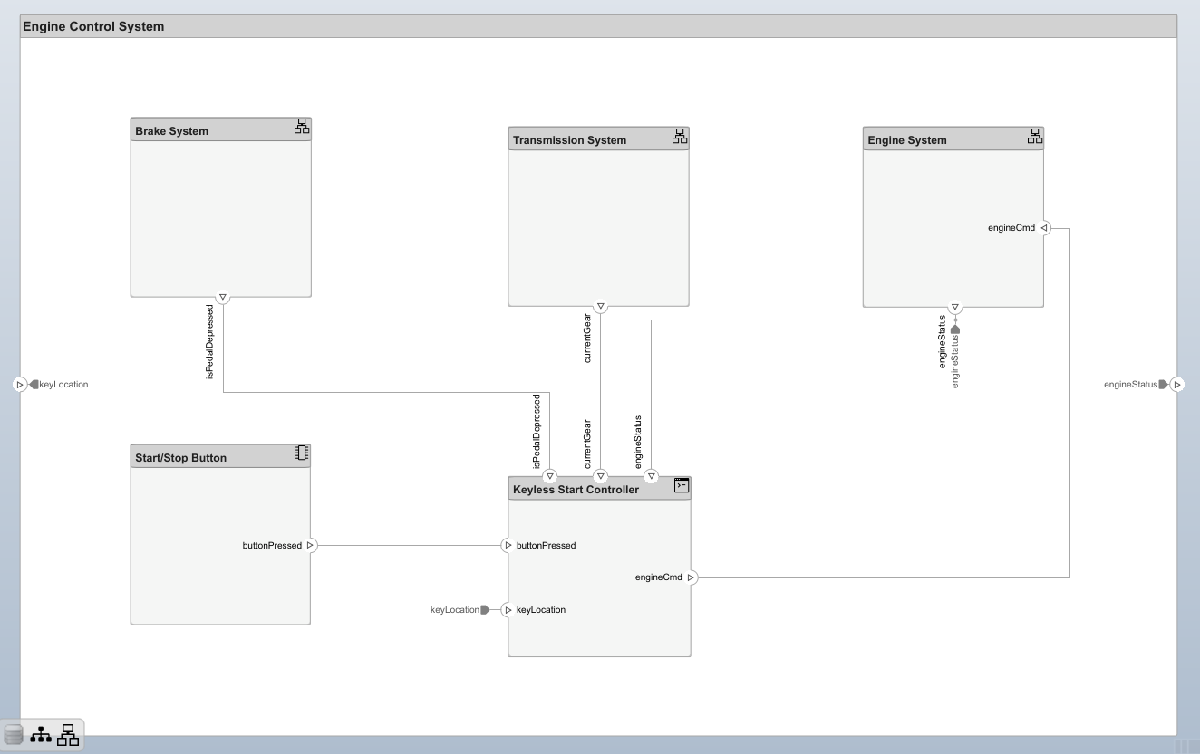

The `keyLocation` signal from the `FOB Locator System` enters the `Keyless Start Controller` component, which receives feedback from the `Brake System`, `Transmission System`, and `Engine System` components. Next, a signal is sent to the `Engine System` to start or stop the vehicle according to the `buttonPressed` signal from the `Start/Stop Button` component.

### Decompose the Lighting System

The keyless entry system sends commands from a lighting controller to activate the headlights and cabin lights.

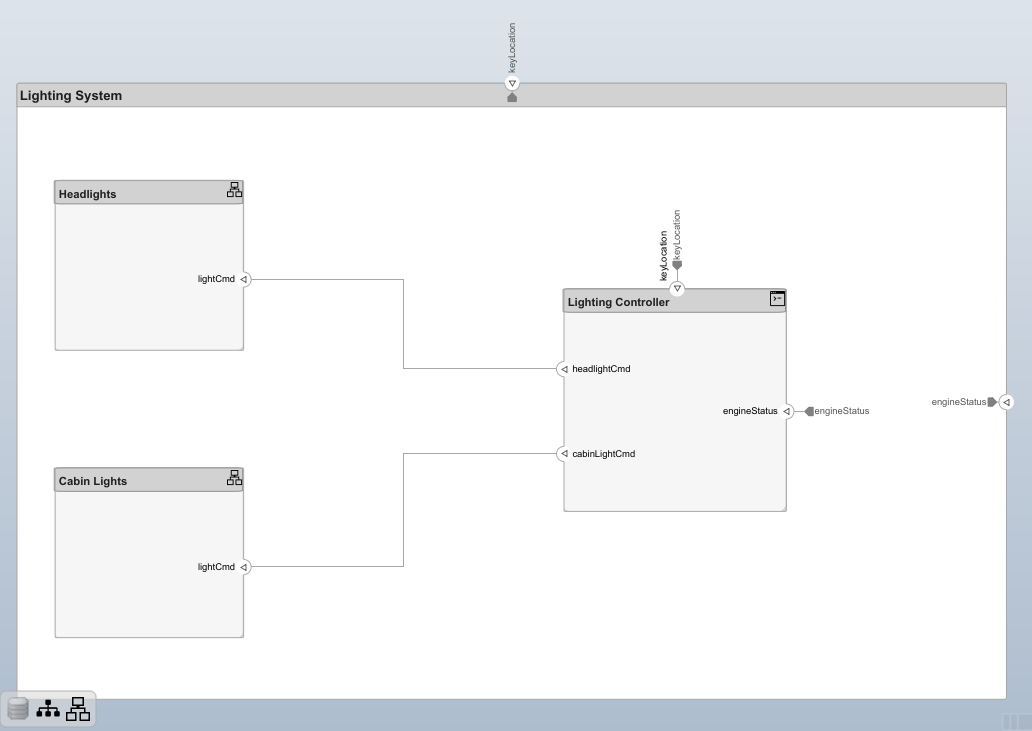

Engine status and key location information sent to the `Lighting Controller` component might activate the different lights represented by the `Headlights` and `Cabin Lights` components.

## **Define Stereotypes to Classify Components**

All components in the architecture have the appropriate stereotype applied. Use the [**Profile Editor**](docid:systemcomposer_ref#mw_ce9cbd7c-4e79-457f-a37b-20883e1eaacf) tool to define profiles, stereotypes, and properties to apply to components, ports, connectors, and interfaces. Each of the component stereotypes inherits properties from the parent stereotype `BaseComponent`. For each stereotyped component, you can define the `Cost`, `ReviewStatus`, or `Latency` property values.

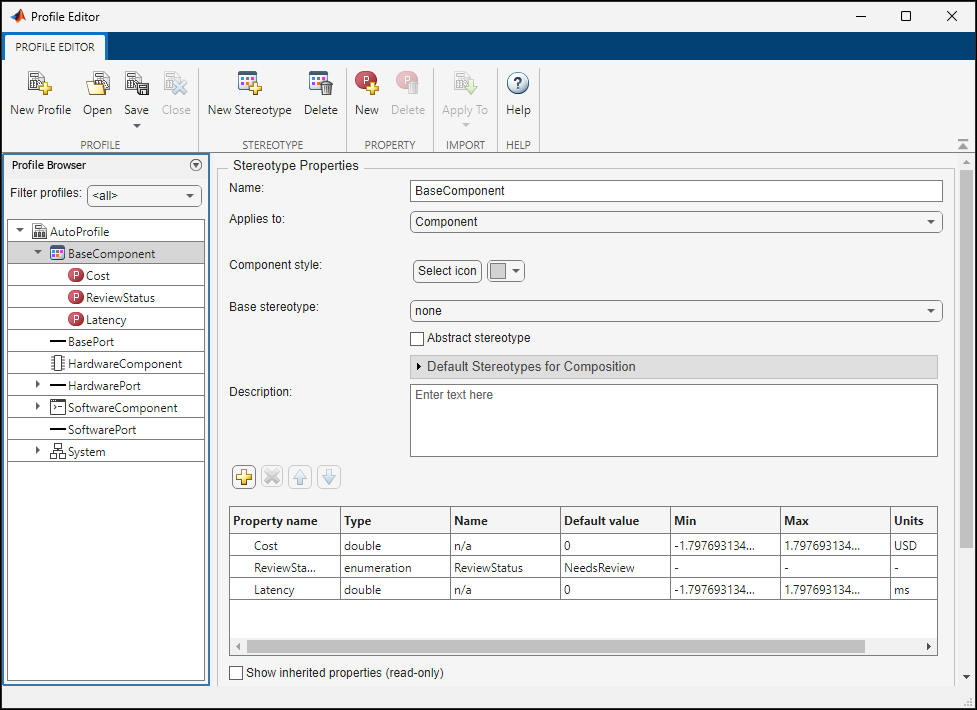

To stereotype components and ports, first apply the profile `AutoProfile` to the top model. Each of the component stereotypes includes an icon that represents the usage of the stereotype and indicates the component type. To apply stereotypes to all model elements in a batch process, use the **Apply Stereotypes** tool. To launch the tool, on the **Modeling** tab in the toolstrip, click **Apply Stereotypes**. To apply stereotypes one by one, use the Property Inspector. For more information, see [Use Stereotypes and Profiles](docid:systemcomposer_ug#mw_e1006fdd-62a9-48ef-a739-4299e460ee9d).

## **Define Port Interfaces to Describe Data Flow**

You can use data interfaces and value types that you assign to ports to decompose the data transfer through those ports along the connections between the ports. For example, the `keyFOBPosition` interface describes the elements of information passing through the `keyLocation` ports to different components of the architecture.

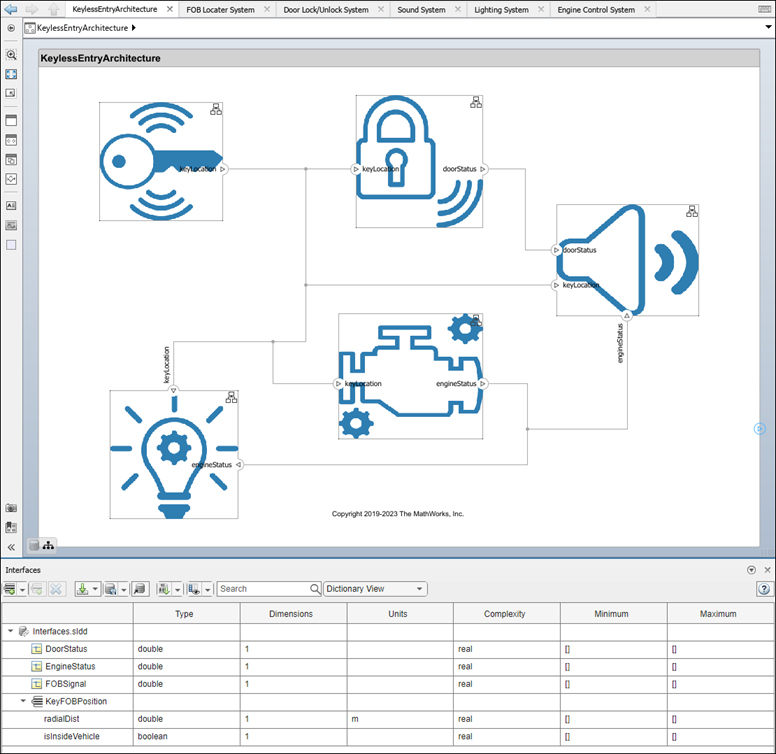

A composite data interface such as `keyFOBPosition` that you decompose into data elements `radialDist` and `isInsideVehicle` is an example of a design in the [**Interface Editor**](docid:systemcomposer_ref#mw_1f4f2646-b52a-428d-9760-fb7c85ffac96). You can also decompose data interfaces by adding data elements typed by other data interfaces or typed by value types like `DoorStatus`, `EngineStatus`, or `FOBSignal`. For more information, see [Assign Interfaces to Ports](docid:systemcomposer_ug#mw_d481cd65-7ba6-4f7d-aae3-7faae9a55c3d).

## **Create Views to Present to Stakeholders**

You can create, view, and edit architecture views in the [**Architecture Views Gallery**](docid:systemcomposer_ref#mw_9981f26d-372d-4416-aa76-9a84e3fadcfc). To launch the tool, on the **Modeling** tab in the toolstrip, click **Architecture Views**. Filtered views update dynamically with changes to the model. Alternatively, you can use Spotlight Views, which are transient views centered on specific components. For more information, see [Create Spotlight Views](docid:systemcomposer_ug#mw_732844c8-6850-46d6-ae7b-c4a3c1f9f741). The `KeylessEntryArchitecture` model has these views:

- Key FOB Position Dataflow — A view of the components in the model that make use of the `KeyFOBPosition` interface.

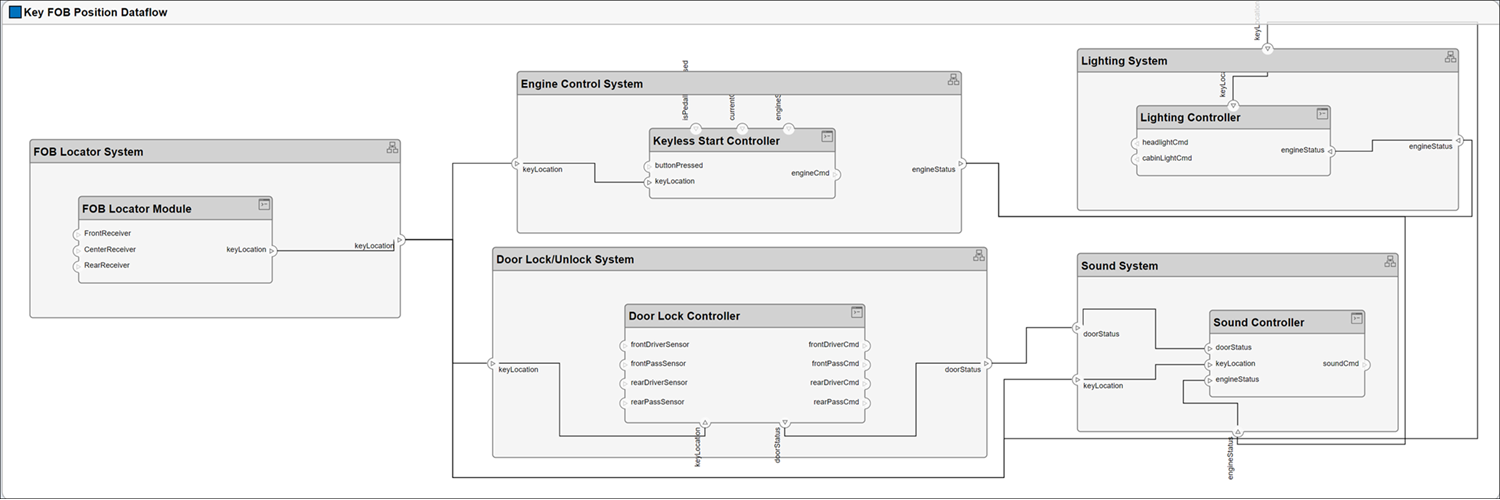

- Door Lock System Supplier Breakdown — A view of the components in the door lock system grouped by which supplier provides the given components.

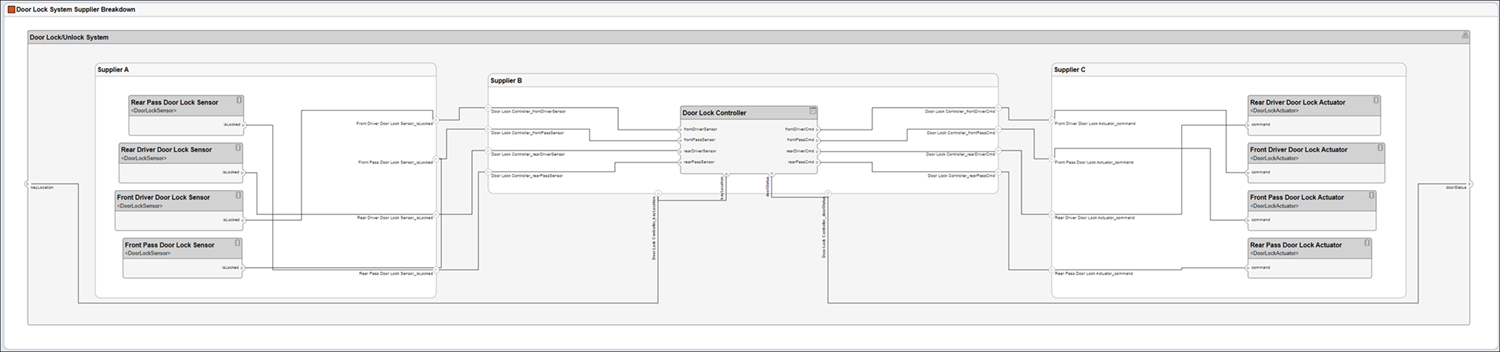

- Sound System Supplier Breakdown — A view of the components in the sound system grouped by which supplier provides the given components.

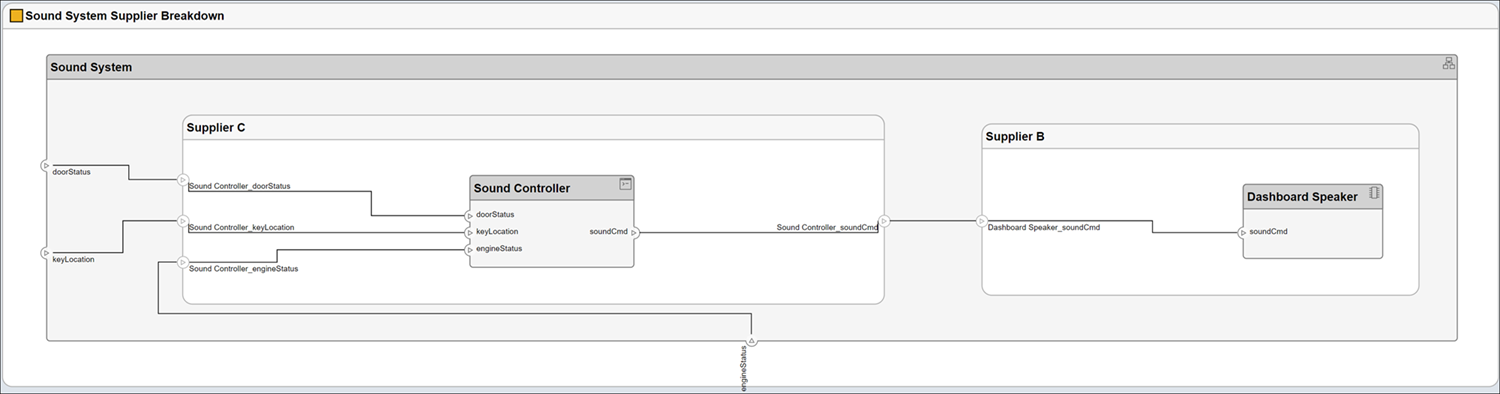

- Software Component Review Status — A view of the components in the model with the `SoftwareComponent` stereotype applied grouped by the value of the `ReviewStatus` property.

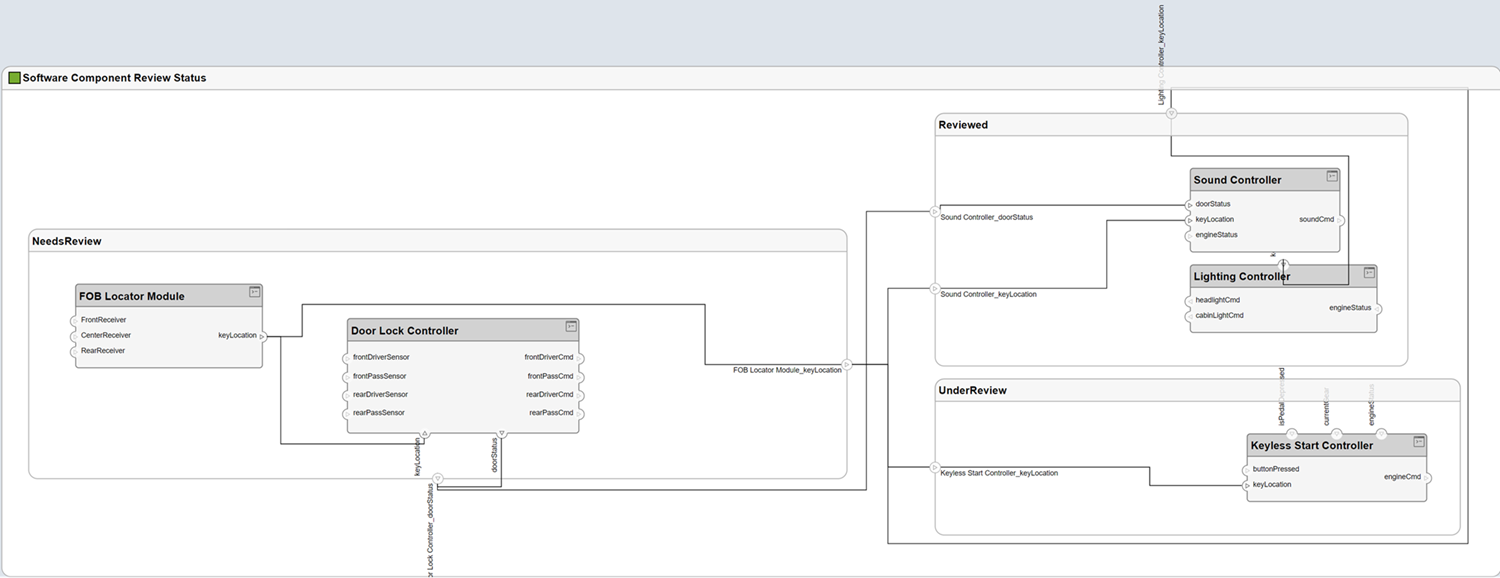

- Top Level Components — A view of the top level components on the architecture model with mask icons.

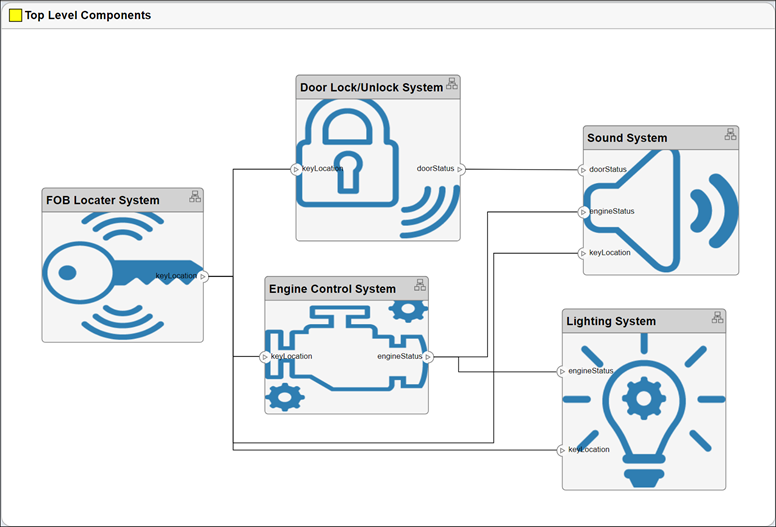

*Copyright 2021 The MathWorks, Inc.*